# **Project 7- Finite Difference Methods for Option Pricing**

1. Consider the following information on the stock of company XYZ: The volatility of the stock  price is $\sigma$ = 20% per annum. Assume the prevailing risk-free rate is r = 4% per annum. Use the X = ln(S) transformation of the Black-Scholes PDE, and $\Delta t$ = 0.002, with $\Delta X$= $\sigma \sqrt{\Delta t}$; then with $\Delta X$ = $\sigma \sqrt{3\Delta t}$; then with$\Delta X$=  $\sigma \sqrt{4\Delta t}$, and a uniform grid (on X) to price  a European Put option with strike price of K = $10, expiration of 0.5-years, and current stock  prices ranging from $4 to $16; using the specified methods below: 

(a) Explicit Finite-Difference method,

dX_time = [1,3,4];
fast_EFD = @(dX_t) EFD(dX_t);
option_price_EFD = arrayfun(@(dX_t) fast_EFD(dX_t),dX_time,'uniformoutput',false);
option_price_EFD = cell2mat(option_price_EFD);
option_price_EFD' % show the put option price

ans =     0.0003    0.0008    0.0039    0.0158    0.0597    0.1956    0.5256    1.0697    1.8849    2.8481    3.8798    4.8498    5.8448
    0.0004    0.0008    0.0044    0.0147    0.0674    0.1869    0.4849    1.0746    1.9467    2.8357    3.8329    4.8456    5.8146
    0.0004    0.0010    0.0033    0.0186    0.0597    0.1954    0.4863    1.0696    1.9505    2.8482    3.8798    4.8498    5.8091


% Black-Scholes Pricing Formula
S0_vec = 16:-1:4;
fast_BSM = @(S0) BSM(S0,"put");
option_price_BMS = arrayfun(@(S0) fast_BSM(S0),S0_vec)% Black-Scholes Pricing for put option

option_price_BMS =     0.0001    0.0006    0.0031    0.0137    0.0525    0.1715    0.4647    1.0244    1.8443    2.8054    3.8021    4.8020    5.8020



% relative error
fast_err = @(i) option_price_EFD(:,i)-option_price_BMS';
relative_err1 = arrayfun(@(i) fast_err(i),1:3,'uniformoutput',false);
relative_err1 = cell2mat(relative_err1);
relative_err1'% show the relative error compared with Black-Scholes Pricing

ans =     0.0002    0.0002    0.0008    0.0021    0.0072    0.0240    0.0610    0.0453    0.0406    0.0428    0.0777    0.0478    0.0429
    0.0003    0.0002    0.0013    0.0010    0.0149    0.0153    0.0203    0.0502    0.1025    0.0304    0.0309    0.0436    0.0126
    0.0003    0.0004    0.0001    0.0050    0.0073    0.0239    0.0216    0.0452    0.1063    0.0428    0.0777    0.0479    0.0071


(b) Implicit Finite-Difference method,  

dX_time = [1,3,4];
fast_IFD = @(dX_t) IFD(dX_t);
option_price_IDF = arrayfun(@(dX_t) fast_IFD(dX_t),dX_time,'uniformoutput',false);
option_price_IDF = cell2mat(option_price_IDF);
option_price_IDF' % show the put option price

ans =     0.0003    0.0007    0.0032    0.0133    0.0514    0.1734    0.4814    1.0059    1.8121    2.7791    3.8203    4.8000    5.8023
    0.0003    0.0007    0.0037    0.0123    0.0581    0.1655    0.4428    1.0108    1.8739    2.7666    3.7730    4.7957    5.7718
    0.0004    0.0009    0.0027    0.0157    0.0514    0.1733    0.4441    1.0059    1.8777    2.7792    3.8203    4.8000    5.7663


% relative error
fast_err = @(i) option_price_IDF(:,i)-option_price_BMS';
relative_err2 = arrayfun(@(i) fast_err(i),1:3,'uniformoutput',false);
relative_err2 = cell2mat(relative_err2);
relative_err2'% show the relative error compared with Black-Scholes Pricing

ans =     0.0002    0.0000    0.0001   -0.0004   -0.0011    0.0019    0.0167   -0.0185   -0.0322   -0.0263    0.0182   -0.0020    0.0003
    0.0002    0.0001    0.0005   -0.0013    0.0057   -0.0060   -0.0219   -0.0136    0.0296   -0.0387   -0.0291   -0.0063   -0.0302
    0.0002    0.0002   -0.0004    0.0021   -0.0010    0.0017   -0.0206   -0.0185    0.0334   -0.0262    0.0182   -0.0020   -0.0357


(c) Crank-Nicolson Finite-Difference method.

dX_time = [1,3,4];
fast_CNFD = @(dX_t) CNFD(dX_t);
option_price_CNDF = arrayfun(@(dX_t) fast_CNFD(dX_t),dX_time,'uniformoutput',false);
option_price_CNDF = cell2mat(option_price_CNDF);
option_price_CNDF' % show the put option price

ans =     0.0003    0.0006    0.0032    0.0132    0.0513    0.1736    0.4817    1.0060    1.8119    2.7790    3.8203    4.8000    5.8023
    0.0003    0.0007    0.0036    0.0123    0.0581    0.1656    0.4431    1.0109    1.8737    2.7665    3.7730    4.7957    5.7718
    0.0003    0.0008    0.0027    0.0157    0.0514    0.1734    0.4444    1.0060    1.8775    2.7791    3.8203    4.8000    5.7663


% relative error
fast_err = @(i) option_price_CNDF(:,i)-option_price_BMS';
relative_err3 = arrayfun(@(i) fast_err(i),1:3,'uniformoutput',false);
relative_err3 = cell2mat(relative_err3);
relative_err3' % show the relative error compared with Black-Scholes Pricing

ans =     0.0002    0.0000    0.0001   -0.0004   -0.0011    0.0020    0.0170   -0.0184   -0.0323   -0.0264    0.0182   -0.0020    0.0003
    0.0002    0.0000    0.0005   -0.0014    0.0057   -0.0059   -0.0216   -0.0135    0.0294   -0.0388   -0.0291   -0.0063   -0.0302
    0.0002    0.0002   -0.0004    0.0020   -0.0011    0.0019   -0.0203   -0.0184    0.0332   -0.0263    0.0182   -0.0020   -0.0357


Inputs: K, $\sigma$, T, $\Delta t$ 

Outputs: i. Values: Pa, Pb and Pc for the European Put option using each of the methods (a),  (b) and (c). ii. Writeup: compare the three methods from (a), (b) and (c) and comment. To  compare, calculate the relative error with respect to the prices derived from Black-Scholes-Merton formula. Do this for current stock prices of $4 to $16 in $1  increments and put them in a table. Put the table and your comments in a .pdf file.

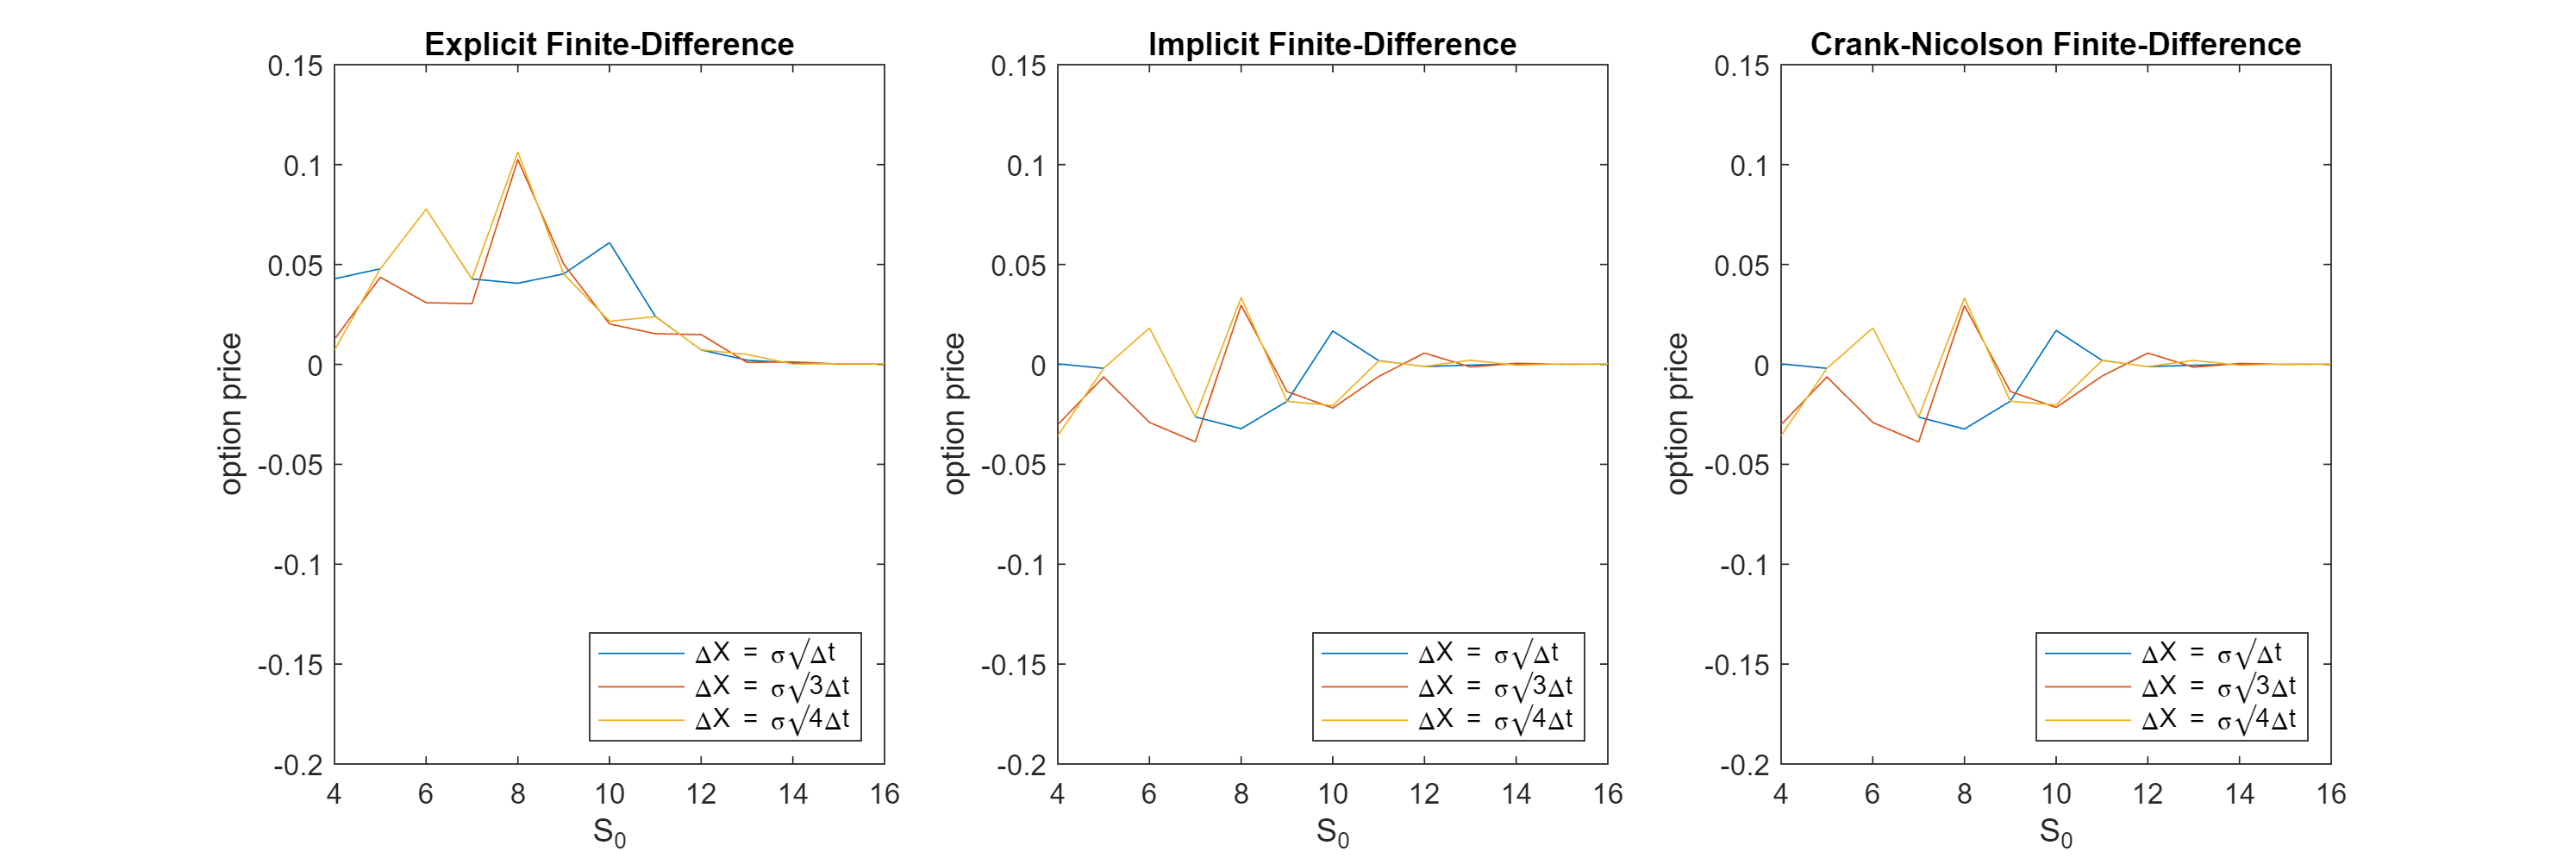

% plot the relative error
figure;
legend_vec = ["\DeltaX = \sigma\surd{\Deltat}","\DeltaX = \sigma\surd{3\Deltat}",...
    "\DeltaX = \sigma\surd{4\Deltat}"];
subplot(1,3,1);
for k = 1:3 
    plot(S0_vec, relative_err1(:,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 1200 400])
legend(legend_vec,...
    'Location','southeast','NumColumns',1)
ylabel("option price")
ylim([-0.2,0.15])
xlabel("S_0")
title("Explicit Finite-Difference")

subplot(1,3,2);
for k = 1:3 
    plot(S0_vec, relative_err2(:,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 1200 400])
legend(legend_vec,...
    'Location','southeast','NumColumns',1)
ylabel("option price")
ylim([-0.2,0.15])
xlabel("S_0")
title("Implicit Finite-Difference")

subplot(1,3,3);
for k = 1:3 
    plot(S0_vec, relative_err3(:,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 1200 400])
legend(legend_vec,...
    'Location','southeast','NumColumns',1)
ylabel("option price")
ylim([-0.2,0.15])
xlabel("S_0")
title("Crank-Nicolson Finite-Difference")

mean(relative_err1.^2,1)

ans =     0.0015    0.0014    0.0019


mean(relative_err2.^2,1)

ans = 1.0e-03 *

    0.2068    0.3772    0.3220


mean(relative_err3.^2,1)

ans = 1.0e-03 *

    0.2086    0.3758    0.3204


**Comments:**

Among the three methods (Explicit Finite-Difference, Implicit Finite-Difference and Crank-Nicolson Finite-Difference Methods), Implicit Finite-Difference Method and Crank-Nicolson Finite-Difference Methods have similar good performance on relative error. However, compared with these two methods, the Explicit Finite-Difference Method has larger relative errors. 

In the selection of $\Delta X$, $\Delta X$= $\sigma \sqrt{3\Delta t}$ and $\Delta X$ =  $\sigma \sqrt{4\Delta t}$ have similar errors, while $\Delta X$= $\sigma \sqrt{\Delta t}$ always produces different error, especially when $S_0 <\$11$. Since the algorithm is proved to be stable and converging when $\Delta X$ $\ge$ $\sigma \sqrt{3\Delta t}$, I believe that the results are better prediction when $\Delta X$= $\sigma \sqrt{3\Delta t}$ or $\Delta X$ =  $\sigma \sqrt{4\Delta t}$.

2. Consider the following information on the stock of company XYZ: The volatility of the stock  price is $\sigma$ = 20% per annum. Assume the prevailing risk-free rate is r = 4% per annum.  Use the Black-Scholes PDE (for S) to price American Call and American Put options with  strike prices of K = $10, expiration of 0.5-years, and current stock prices for a range from $4  to $16; using the specified methods below: 

(a) Explicit Finite-Difference method, 

dX_time = [0.5, 1];
fast_EFD = @(dX_t) EFD_am(dX_t);
[option_price_EFDam_call,option_price_EFDam_put] = arrayfun(@(dX_t) fast_EFD(dX_t),dX_time,'uniformoutput',false);
option_price_EFDam_call = cell2mat(option_price_EFDam_call);% transfer from cell to matrix
option_price_EFDam_call'% show the call option price

ans =     6.1987    5.1989    4.2013    3.2116    2.2488    1.3642    0.6540    0.2167    0.0421    0.0041    0.0002    0.0000    0.0000
    6.1995    5.1994    4.2019    3.2116    2.2450    1.3481    0.6230    0.2010    0.0429    0.0059    0.0005    0.0000    0.0000


option_price_EFDam_put = cell2mat(option_price_EFDam_put);% transfer from cell to matrix
option_price_EFDam_put'% show the put option price

ans =     0.0005    0.0008    0.0033    0.0138    0.0519    0.1707    0.4733    1.0757    2.0000    3.0000    4.0000    5.0000    6.0000
    0.0013    0.0013    0.0039    0.0139    0.0482    0.1545    0.4400    1.0516    2.0000    3.0000    4.0000    5.0000    6.0000


 (b) Implicit Finite-Difference method, 

dX_time = [0.5, 1];
fast_IFD = @(dX_t) IFD_am(dX_t);
[option_price_IFDam_call,option_price_IFDam_put] = arrayfun(@(dX_t) fast_IFD(dX_t),dX_time,'uniformoutput',false);
option_price_IFDam_call = cell2mat(option_price_IFDam_call);% transfer from cell to matrix
option_price_IFDam_call'% show the call option price

ans =     6.1985    5.1988    4.2014    3.2117    2.2489    1.3638    0.6534    0.2166    0.0424    0.0042    0.0002    0.0000    0.0000
    6.1993    5.1993    4.2019    3.2117    2.2451    1.3479    0.6223    0.2011    0.0432    0.0060    0.0005    0.0000    0.0000


option_price_IFDam_put = cell2mat(option_price_IFDam_put); % transfer from cell to matrix
option_price_IFDam_put'% show the put option price

ans =     0.0005    0.0009    0.0034    0.0139    0.0519    0.1703    0.4725    1.0752    2.0000    3.0000    4.0000    5.0000    6.0000
    0.0013    0.0013    0.0040    0.0140    0.0483    0.1542    0.4391    1.0513    2.0000    3.0000    4.0000    5.0000    6.0000


(c) Crank-Nicolson Finite-Difference method. 

dX_time = [0.5, 1];
fast_CNFD = @(dX_t) CNFD_am(dX_t);
[option_price_CNFDam_call,option_price_CNFDam_put] = arrayfun(@(dX_t) fast_CNFD(dX_t),dX_time,'uniformoutput',false);
option_price_CNFDam_call = cell2mat(option_price_CNFDam_call);% transfer from cell to matrix
option_price_CNFDam_call'% show the call option price

ans =     6.1985    5.1988    4.2013    3.2116    2.2489    1.3640    0.6537    0.2166    0.0422    0.0041    0.0002    0.0000    0.0000
    6.1993    5.1993    4.2018    3.2117    2.2450    1.3480    0.6227    0.2010    0.0431    0.0060    0.0005    0.0000    0.0000


option_price_CNFDam_put = cell2mat(option_price_CNFDam_put);% transfer from cell to matrix
option_price_CNFDam_put'% show the put option price

ans =     0.0005    0.0008    0.0034    0.0138    0.0519    0.1705    0.4729    1.0755    2.0000    3.0000    4.0000    5.0000    6.0000
    0.0013    0.0013    0.0039    0.0140    0.0482    0.1543    0.4395    1.0514    2.0000    3.0000    4.0000    5.0000    6.0000


Choose $\Delta t$ = 0.002, with $\Delta S$ = 0.5, or with $\Delta S$ = 1. 

Inputs: K, $\sigma$, T, $\Delta t$ 

Outputs: i. Values: Ca, Cb, Cc, Pa, Pb and Pc and for the American call and put options using  each of the methods (a), (b) and (c). ii. Graphs: Plot the American Call option price as a function of the current stock price  from $4 to $16 in $1 increments for methods (a), (b) and (c) on the same graph.  Use a color legend or linestyles to differentiate the plots. Do the same for the  American Put option in another graph. Place the two graphs in a .pdf file.

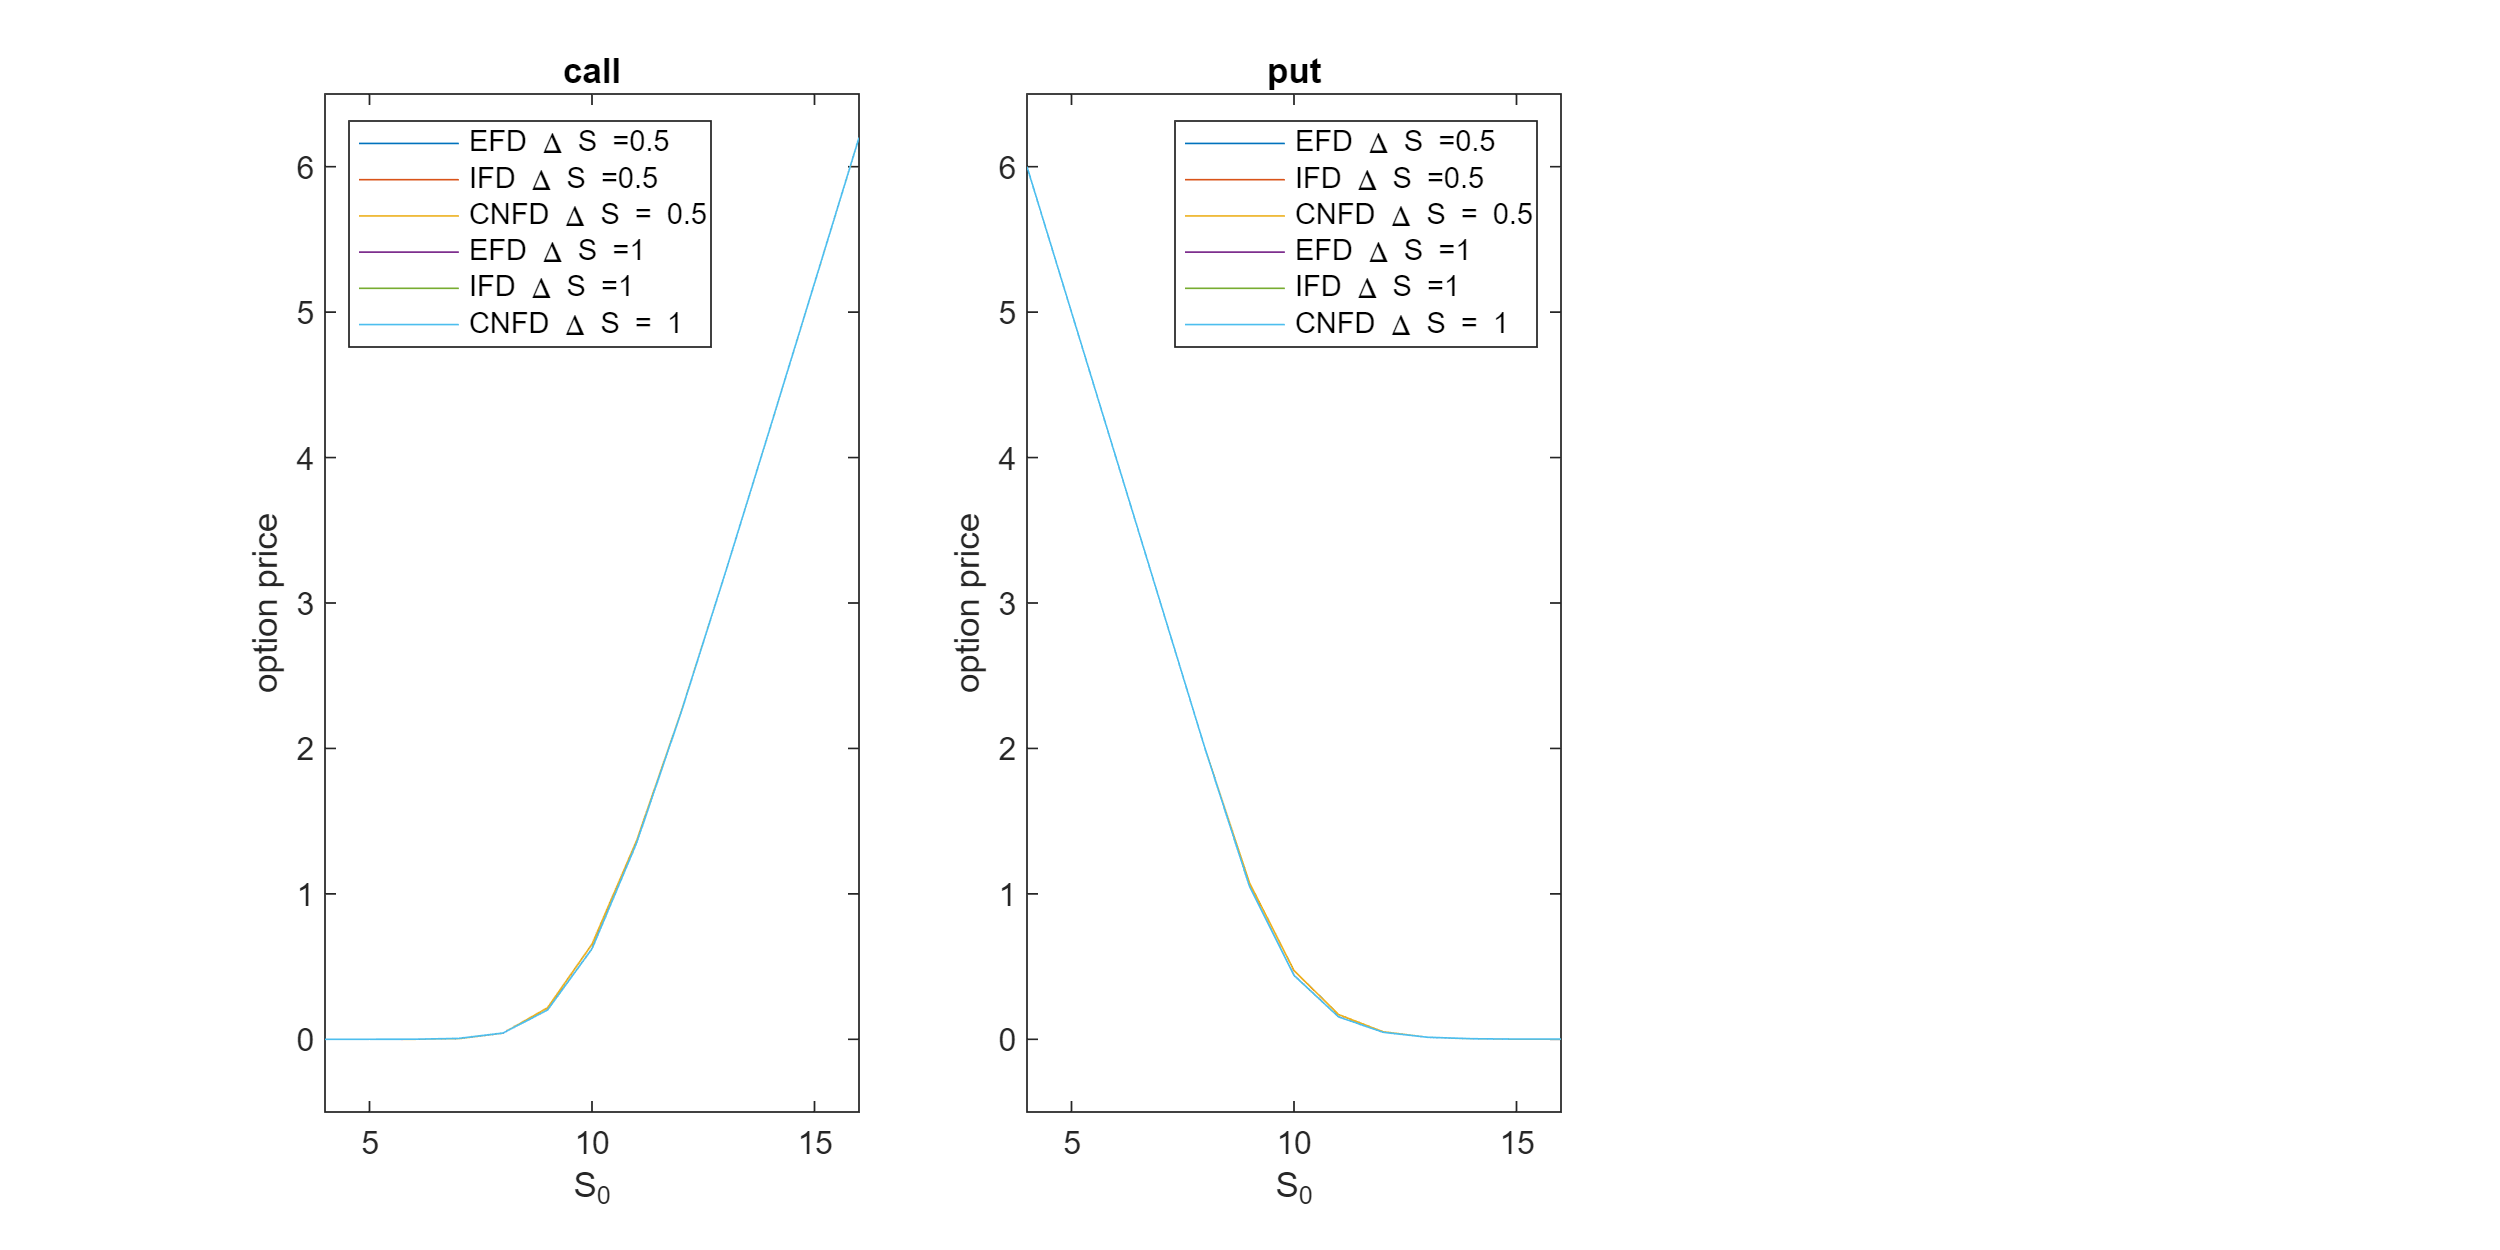

% plot
figure;
legend_vec = ["EFD \Delta S =0.5","IFD \Delta S =0.5","CNFD \Delta S = 0.5",...
    "EFD \Delta S =1","IFD \Delta S =1","CNFD \Delta S = 1"];
subplot(1,3,1);
for k = 1:2 
    plot(S0_vec, option_price_EFDam_call(:,k))
    hold on
    plot(S0_vec, option_price_IFDam_call(:,k))
    hold on
    plot(S0_vec, option_price_CNFDam_call(:,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 1000 500])
legend(legend_vec,...
    'Location','northwest','NumColumns',1)
ylabel("option price")
ylim([-0.5,6.5])
xlabel("S_0")
title("call")

subplot(1,3,2);
for k = 1:2 
    plot(S0_vec, option_price_EFDam_put(:,k))
    hold on
    plot(S0_vec, option_price_IFDam_put(:,k))
    hold on
    plot(S0_vec, option_price_CNFDam_put(:,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 1000 500])
legend(legend_vec,...
    'Location','northeast','NumColumns',1)
ylabel("option price")
ylim([-0.5,6.5])
xlabel("S_0")
title("put")

Functions used in the previous codes:

function option_price = BSM(S0, type)
    sigma=0.2; r=0.04; K=10; T=0.5; 
    d1 = (log(S0/K) + (r+sigma^2/2)*T)/(sigma*sqrt(T));
    d2 = d1-sigma*sqrt(T);
    if type=="call"
        option_price = normcdf(d1)*S0-normcdf(d2)*K*exp(-r*T);
    elseif type == "put"
        option_price = normcdf(-d2)*K*exp(-r*T)-normcdf(-d1)*S0;
    else
        % other input: return empty vector
        option_price = [];
    end
end

function option_price = EFD(dX_times)
% Explicit Finite-Difference method for put option
    Smin = 4; Smax = 16; Xmin = log(Smin); Xmax = log(Smax);
    sigma = 0.2; r = 0.04; dt = 0.002;
    K = 10; T = 0.5;
    M = ceil(T/dt);
    dX = sigma*sqrt(dX_times*dt); 
    N = ceil(((Xmax-Xmin)/dX)/2); % build a grid with shape (2N+1, M)
    
    % Pu, Pm, Pd
    P_u = dt*(sigma^2/(2*(dX^2))+(r-sigma^2)/(2*dX));
    P_m = 1-dt*(sigma/dX)^2-r*dt;
    P_d = dt*(sigma^2/(2*(dX^2))-(r-sigma^2)/(2*dX));
    
    % matrix A
    A_mat = zeros(2*N+1);
    for i=1:2*N+1
        if i == 1  % max
            A_mat(i,1:3) = [P_u,P_m,P_d];
        elseif i == 2*N+1  % min
            A_mat(i,i-2:i) = [P_u,P_m,P_d];
        else
            A_mat(i,i-1:i+1) = [P_u,P_m,P_d];
        end
    end

    % the stock price at the grid made up of X
    S_vec = 1:(2*N+1); S_vec(1) = Smax;
    % the current stock price whose the option price will be returned
    S_vec_return = 16:-1:4;j=1;
    % find the index that the price should be returned
    S_idx = 4:16; min0 = 1;
    for i = 1:(2*N+1)
        if i ~= 1
        % -delta S = S_end * (exp(-delta X)-1), where X=lnS
            S_vec(i) = S_vec(i-1)*exp(-dX);
        end
        diff = abs(S_vec(i) - S_vec_return(j));
        if diff <= min0
            min0 = diff;
            S_idx(j) = i;
        else% diff > min0
            min0 = 1;
            j = j+1;
        end
    end
    
    F_vec = max(K-S_vec',0);
    for i=1:M
        B_vec = zeros(2*N+1,1); B_vec(2*N+1,1) = S_vec(2*N)-S_vec(2*N+1);
        F_vec = A_mat*F_vec + B_vec; % F_t = A*F_(t+1)+B
    end
    option_price = F_vec(S_idx);
end

function [option_price_call,option_price_put] = EFD_am(dS)
% Explicit Finite-Difference method for American call and put option
    Smin=4; Smax=16;
    sigma=0.2; r=0.04; dt=0.002;
    K=10; T=0.5;
    % build a grid with shape (2N+1, M)
    % unit: # of deltas in the $1 gap of Stock Price
    unit = ceil(1/dS); N = unit * ceil((Smax-Smin)/2); 
    S0 = Smin+N*dS; M = ceil(T/dt);
    
    % Pu, Pm, Pd
    j_vec = (16*unit):-1:(4*unit);
    P_u = dt*((sigma*j_vec).^2+r*j_vec)/2;
    P_m = 1-dt*((sigma*j_vec).^2+r);
    P_d = dt*((sigma*j_vec).^2-r*j_vec)/2;
    
    % matrix A
    A_mat = zeros(2*N+1);
    for i=1:2*N+1
        if i == 1  % max
            A_mat(i,1:3) = [P_u(i),P_m(i),P_d(i)];
        elseif i == 2*N+1  % min
            A_mat(i,i-2:i) = [P_u(i),P_m(i),P_d(i)];
        else
            A_mat(i,i-1:i+1) = [P_u(i),P_m(i),P_d(i)];
        end
    end
    
    S_vec = (dS*N:-dS:-dS*N)+S0;
    
    % call option price
    F_vec = max(S_vec' - K,0);
    standard = F_vec;
    for i=1:M
        B_vec = zeros(2*N+1,1); B_vec(1,1) = dS;
        F_vec = A_mat*F_vec + B_vec;
        idx = standard>F_vec; % update the early exercise
        F_vec(idx) = standard(idx);
    end
    S_vec0_idx = 1:unit:(2*N+1);
    option_price_call = F_vec(S_vec0_idx);

    % put option price
    F_vec = max(K-S_vec',0);
    standard = F_vec;
    for i=1:M
        B_vec = zeros(2*N+1,1); B_vec(2*N+1,1) = dS;
        F_vec = A_mat*F_vec + B_vec; % F_t = A*F_(t+1)+B
        idx = standard>F_vec; % update the early exercise
        F_vec(idx) = standard(idx);
    end
    option_price_put = F_vec(S_vec0_idx);
end

function option_price = IFD(dX_times)
% Implicit Finite-Difference method for put option
    Smin = 4; Smax = 16; Xmin = log(Smin); Xmax = log(Smax);
    sigma = 0.2; r = 0.04; dt = 0.002;
    K = 10; T = 0.5;
    % build a grid with shape (2N+1, M)
    % unit: # of deltas in the $1 gap of Stock Price
    M = ceil(T/dt);
    dX = sigma*sqrt(dX_times*dt); 
    N = ceil(((Xmax-Xmin)/dX)/2);
    
    % Pu, Pm, Pd
    P_u = -1/2*dt*(sigma^2/(dX^2)+(r-sigma^2/2)/dX);
    P_m = 1+dt*(sigma/dX)^2+r*dt;
    P_d = -1/2*dt*(sigma^2/(dX^2)-(r-sigma^2/2)/dX);
    
    A_mat = zeros(2*N+1);
    for i=1:2*N+1
        if i == 1  % max
            A_mat(i,1:2) = [1,-1];
        elseif i == 2*N+1  % min
            A_mat(i,i-1:i) = [1,-1];
        else
            A_mat(i,i-1:i+1) = [P_u,P_m,P_d];
        end
    end
    
    % the stock price at the grid made up of X
    S_vec = 1:(2*N+1); S_vec(1) = Smax;
    % the current stock price whose the option price will be returned
    S_vec_return = 16:-1:4;j=1;
    % find the index that the price should be returned
    S_idx = 4:16; min0 = 1;
    for i = 1:(2*N+1)
        if i ~= 1
            S_vec(i) = S_vec(i-1)*exp(-dX);
        end
        diff = abs(S_vec(i) - S_vec_return(j));
        if diff <= min0
            min0 = diff;
            S_idx(j) = i;
        else% diff > min0
            min0 = 1;
            j = j+1;
        end
    end
    
    F_vec = max(K-S_vec',0);
    for i=1:M
        F_vec(2*N+1,1) = -S_vec(2*N)+S_vec(2*N+1); F_vec(1,1) = 0;
        F_vec = A_mat\F_vec; % A * F_t = F_(t+1) => F_t = inv(A)*F_(t+1)
    end

    option_price = F_vec(S_idx);
end

function [option_price_call,option_price_put] = IFD_am(dS)
% Implicit Finite-Difference method for American call and put option
    Smin=4;Smax=16;
    sigma=0.2; r=0.04; dt=0.002;
    K=10; T=0.5;
    % build a grid with shape (2N+1, M)
    % unit: # of deltas in the $1 gap of Stock Price
    M = ceil(T/dt); 
    unit = ceil(1/dS); N = unit * ceil((Smax-Smin)/2);
    S0 = Smin+N*dS;
    
    j_vec = (16*unit):-1:(4*unit);
    P_u = -dt*((sigma*j_vec).^2+r*j_vec)/2;
    P_m = 1+dt*((sigma*j_vec).^2+r);
    P_d = -dt*((sigma*j_vec).^2-r*j_vec)/2;
    
    A_mat = zeros(2*N+1);
    for i=1:2*N+1
        if i == 1  % max
            A_mat(i,1:2) = [1,-1];
        elseif i == 2*N+1  % min
            A_mat(i,i-1:i) = [1,-1];
        else
            A_mat(i,i-1:i+1) = [P_u(i),P_m(i),P_d(i)];
        end
    end
    
    S_vec = (dS*N:-dS:-dS*N)+S0;
    
    % call option price
    F_vec = max(S_vec'-K,0);
    standard = F_vec;
    for i=1:M
        F_vec(1,1) = dS; F_vec(2*N+1,1) = 0;
        F_vec = A_mat\F_vec;
        idx = standard>F_vec; % update the early exercise
        F_vec(idx) = standard(idx);
    end
    S_vec0_idx = 1:unit:(2*N+1);
    option_price_call = F_vec(S_vec0_idx);

    % put option price
    F_vec = max(K-S_vec',0);
    standard = F_vec;
    for i=1:M
        F_vec(2*N+1,1) = -dS; F_vec(1,1) = 0;
        F_vec = A_mat\F_vec;% A * F_t = F_(t+1) => F_t = inv(A)*F_(t+1)
        idx = standard>F_vec; % update the early exercise
        F_vec(idx) = standard(idx);
    end
    option_price_put = F_vec(S_vec0_idx);
end



function option_price = CNFD(dX_times)
% Crank-Nicolson Finite-Difference method for put option
    Smin = 4; Smax = 16; Xmin = log(Smin); Xmax = log(Smax);
    sigma = 0.2; r = 0.04; dt = 0.002;
    K = 10; T = 0.5;
    % build a grid with shape (2N+1, M)
    % unit: # of deltas in the $1 gap of Stock Price
    M = ceil(T/dt);
    dX = sigma*sqrt(dX_times*dt); 
    N = ceil(((Xmax-Xmin)/dX)/2);
    
    P_u = -1/4*dt*(sigma^2/(dX^2)+(r-sigma^2/2)/dX);
    P_m = 1 + dt/2*(sigma/dX)^2+r*dt/2;
    P_d = -1/4*dt*(sigma^2/(dX^2)-(r-sigma^2/2)/dX);
    % matrix A
    A_mat = zeros(2*N+1);
    for i=1:2*N+1
        if i == 1  % max
            A_mat(i,1:2) = [1,-1];
        elseif i == 2*N+1  % min
            A_mat(i,i-1:i) = [1,-1];
        else
            A_mat(i,i-1:i+1) = [P_u,P_m,P_d];
        end
    end
    % matrix B
    B_mat = A_mat;
    for i=1:2*N+1
        if (i ~= 1) && (i ~= 2*N+1)
            B_mat(i,i-1:i+1) = [-P_u,-P_m+2,-P_d];
        end
    end
    % the stock price at the grid made up of X
    S_vec = 1:(2*N+1); S_vec(1) = Smax;
    % the current stock price whose the option price will be returned
    S_vec_return = 16:-1:4;j=1;
    % find the index that the price should be returned
    S_idx = 4:16; min0 = 1;
    for i = 1:(2*N+1)
        if i ~= 1
            S_vec(i) = S_vec(i-1)*exp(-dX);
        end
        diff = abs(S_vec(i) - S_vec_return(j));
        if diff <= min0
            min0 = diff;
            S_idx(j) = i;
        else % diff > min0
            min0 = 1;
            j = j+1;
        end
    end
    
    F_vec = max(K-S_vec',0);
    for i=1:M
        % build z vector
        z_vec = B_mat*F_vec;
        z_vec(2*N+1,1) = -S_vec(2*N)+S_vec(2*N+1); z_vec(1,1) = 0;
        F_vec = A_mat\z_vec;% A * F = Z => F = inv(A)*Z
    end
    option_price = F_vec(S_idx);
end


function [option_price_call,option_price_put] = CNFD_am(dS)
% Crank-Nicolson Finite-Difference method for American call and put option
    Smin=4;Smax=16;
    sigma=0.2; r=0.04; dt=0.002;
    K=10; T=0.5;
    % build a grid with shape (2N+1, M)
    % unit: # of deltas in the $1 gap of Stock Price
    M = ceil(T/dt);
    unit = ceil(1/dS); N = unit * ceil((Smax-Smin)/2);
    S0 = Smin+N*dS;
    
    % Pu, Pm, Pd
    j_vec = (16*unit):-1:(4*unit);
    P_u = -dt*((sigma*j_vec).^2+r*j_vec)/4;
    P_m = 1+dt*((sigma*j_vec).^2+r)/2;
    P_d = -dt*((sigma*j_vec).^2-r*j_vec)/4;
    
    
    A_mat = zeros(2*N+1);
    for i=1:2*N+1
        if i == 1  % max
            A_mat(i,1:2) = [1,-1];
        elseif i == 2*N+1  % min
            A_mat(i,i-1:i) = [1,-1];
        else
            A_mat(i,i-1:i+1) = [P_u(i),P_m(i),P_d(i)];
        end
    end

    B_mat = A_mat;
    for i=1:2*N+1
        if (i ~= 1) && (i ~= 2*N+1)
            B_mat(i,i-1:i+1) = [-P_u(i),-P_m(i)+2,-P_d(i)];
        end
    end
    
    S_vec = (dS*N:-dS:-dS*N)+S0;
    
    % call option price
    F_vec = max(S_vec'-K,0);
    standard = F_vec;
    for i=1:M
        z_vec = B_mat*F_vec;
        z_vec(1,1) = dS; z_vec(2*N+1,1) = 0;
        F_vec = A_mat\z_vec; % A * F = Z => F = inv(A)*Z
        idx = standard>F_vec; % update the early exercise
        F_vec(idx) = standard(idx);
    end
    S_vec0_idx = 1:unit:(2*N+1);
    option_price_call = F_vec(S_vec0_idx);

    % put option price
    F_vec = max(K-S_vec',0);
    standard = F_vec;
    for i=1:M
        z_vec = B_mat*F_vec;
        z_vec(2*N+1,1) = -dS; z_vec(1,1) = 0;
        F_vec = A_mat\z_vec;
        idx = standard>F_vec; % update the early exercise
        F_vec(idx) = standard(idx);
    end
    option_price_put = F_vec(S_vec0_idx);
end